## Datastores 

Create image datastore with the MNIST dataset

file_loc= 'C:\Program Files\MATLAB\R2020b\toolbox\nnet\nndemos\nndatasets\DigitDataset'

file_loc = 'C:\Program Files\MATLAB\R2020b\toolbox\nnet\nndemos\nndatasets\DigitDataset'

imds = imageDatastore(file_loc,'IncludeSubfolders',true,'LabelSource',"foldernames")

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\R2020b\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image10000.png';
                              ' ...\R2020b\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9001.png';
                              ' ...\R2020b\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9002.png'
                               ... and 9997 more
                              }
                     Folders: {
                              ' ...\MATLAB\R2020b\toolbox\nnet\nndemos\nndatasets\DigitDataset'
                              }
                      Labels: [0; 0; 0 ... and 9997 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn:

Read a batch

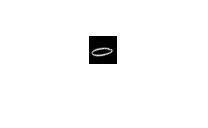

read(imds)

More information about datastores can be found at:

[Datastore - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/matlab/datastore.html)

## Stochastic Gradient Descent with Momentum

MATLAB provides multiple different optimizers for performing gradient descent. The basic gradient has the following formula:

A more advanced optimization algorithm is SGDM (stochastic Gradient Descent with Momentum). This basically keeps track of exponentially weighted average of previous gradients in the form a momentum in the direction of gradient. Its formula is :

alpha = learning rate (hyperparameter) 

gamma = momentum (hyperparameter) := how much of previous gradients do you wish to remember.

The difference of weights at step = l and step = l-1 is called 'velocity'.

We first define our hyperparameters:

params=[0,0,0];
grad=[1,1,1];
vel=[];
learning_rate = 0.1;
momentum = 0.95;

Now lets perform an SGDM update.

[params,vel] = sgdmupdate(params,grad,vel,learning_rate,momentum);

Check out the output.

params

params =    -0.1000   -0.1000   -0.1000


More details about SGDM and other optimizers can be found at:

[Options for training deep learning neural network - MATLAB trainingOptions (mathworks.com)](https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html#bu80qkw-3_head)